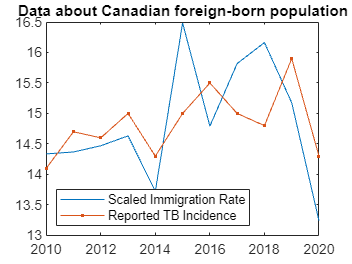

yearGrid = 2010:2020;
ReportedImmigration = [259110 260036 263101 267924 240763 323192 272707 303325 313601 284157 226309]; %immigration into canada 2010-2020
ReportedTB = [14.1 14.7 14.6 15 14.3 15 15.5 15 14.8 15.9 14.3]; %Actual TB rate from 2010 - 2020



figure(1);clf;
plot(yearGrid,(ReportedImmigration-mean(ReportedImmigration))/std(ReportedImmigration)+mean(ReportedTB),'DisplayName','Scaled Immigration Rate')
hold on
plot(yearGrid, ReportedTB,'.-','DisplayName','Reported TB Incidence')
legend('Location','SouthWest')
title('Data about Canadian foreign-born population')

saveas(gcf, 'foreignBornData.png')